clc; clear all; close all;
run('variableLoader.m')
%INPUTS
sim('inputs.slx');
load('sine_sweep.mat')
sine = squeeze(sine_sweep.Data);
input = timetable(sine,'SampleRate',50);

# short period mode(5secs)

paramStruct.StopTime = "5";

## elevator to pitch rate

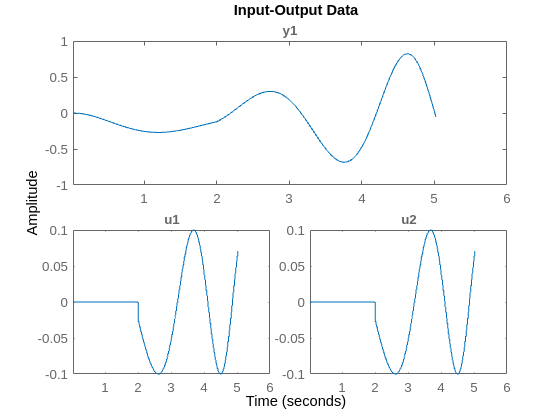

out = sim('el_t_pr',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y = squeeze(out.pitch_rate);
data = iddata(y,u,0.02);
plot(data)

sys_el_t_pr= tfest(data, 3, 2)

sys_el_t_pr =
  From input "u1" to output "y1":
    22.63 s^2 - 77.82 s + 287.7
  --------------------------------
  s^3 + 2.694 s^2 + 24.8 s + 35.87
 
  From input "u2" to output "y1":
    -17.3 s^2 - 18.38 s - 386.5
  --------------------------------
  s^3 + 1.51 s^2 + 34.29 s + 49.84
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [3 3]   Number of zeros: [2 2]
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 92.4%                    
FPE: 0.0008158, MSE: 0.0007067                   
 


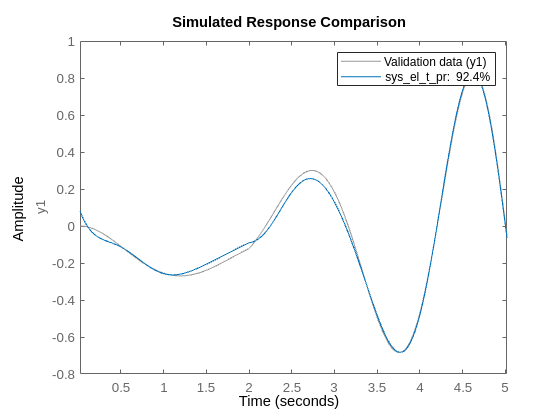

compare(data,sys_el_t_pr)

## elevator to aoa

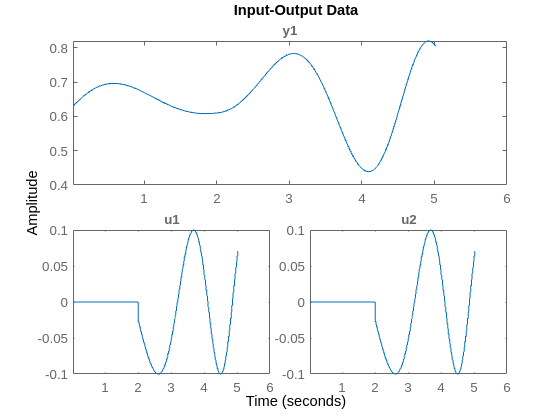

out = sim('el_t_a',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y = squeeze(out.aoa);
data = iddata(y,u,0.02);
plot(data)

sys_el_t_a= tfest(data, 4, 1)

sys_el_t_a =
  From input "u1" to output "y1":
                 -6.472 s + 65.57
  -----------------------------------------------
  s^4 + 0.3939 s^3 + 16.36 s^2 + 5.14 s + 0.01914
 
  From input "u2" to output "y1":
                 -17.53 s + 16.7
  ---------------------------------------------
  s^4 + 0.4087 s^3 + 16.9 s^2 + 5.789 s + 1.306
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [4 4]   Number of zeros: [1 1]
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 64.89%                   
FPE: 0.001218, MSE: 0.001039                     
 


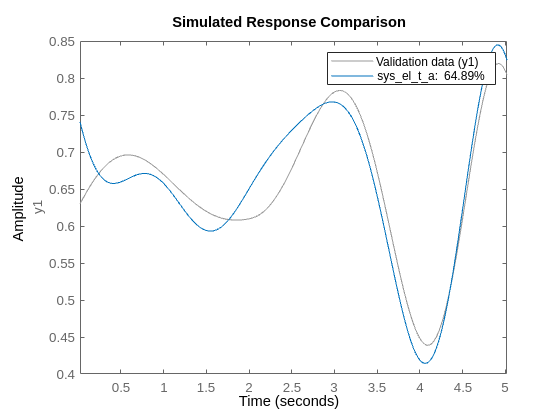

compare(data,sys_el_t_a)

# Phugoid mode(20secs)

paramStruct.StopTime = "20";

## elevator to velocity

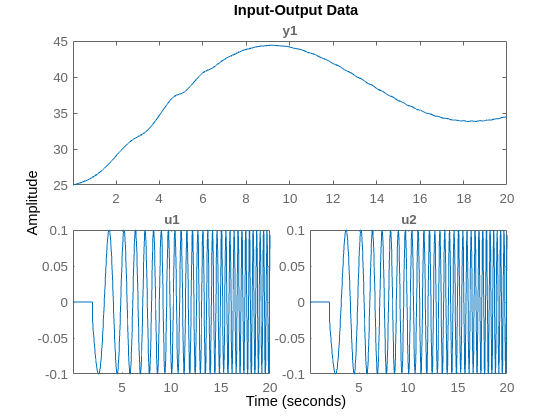

out = sim('el_t_v',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y = squeeze(out.velocity);
data = iddata(y,u,0.02);
plot(data)

sys_el_t_v= tfest(data, 3, 2)

sys_el_t_v =
  From input "u1" to output "y1":
         353 s^2 + 3241 s - 407
  ------------------------------------
  s^3 + 3.052 s^2 + 1.324 s + 0.001885
 
  From input "u2" to output "y1":
      -687.8 s^2 - 3218 s - 1576
  -----------------------------------
  s^3 + 2.209 s^2 + 1.787 s + 0.08281
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [3 3]   Number of zeros: [2 2]
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 43.85%                   
FPE: 9.537, MSE: 9.2                             
 


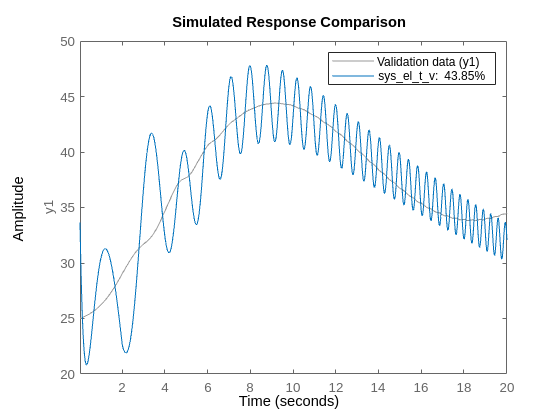

compare(data,sys_el_t_v)

## elevator to height

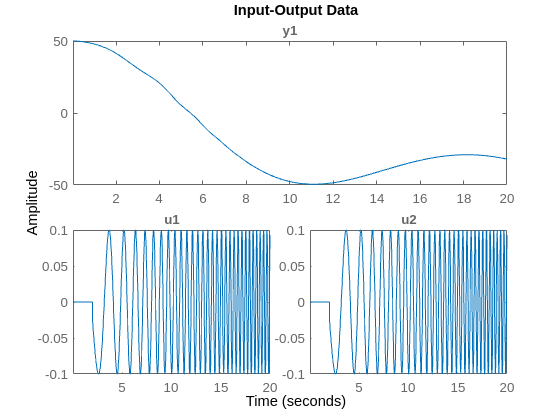

out = sim('el_t_h',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y = squeeze(out.height);
data = iddata(y,u,0.02);
plot(data)

sys_el_t_h= tfest(data, 4, 1)

sys_el_t_h =
  From input "u1" to output "y1":
                   -633.2 s + 26.2
  --------------------------------------------------
  s^4 + 0.914 s^3 + 0.7128 s^2 + 0.1792 s + 0.004733
 
  From input "u2" to output "y1":
                  -4647 s + 806.4
  -----------------------------------------------
  s^4 + 2.358 s^3 + 2.757 s^2 + 1.094 s + 0.08943
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [4 4]   Number of zeros: [1 1]
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 79.13%                   
FPE: 46.84, MSE: 45                              
 


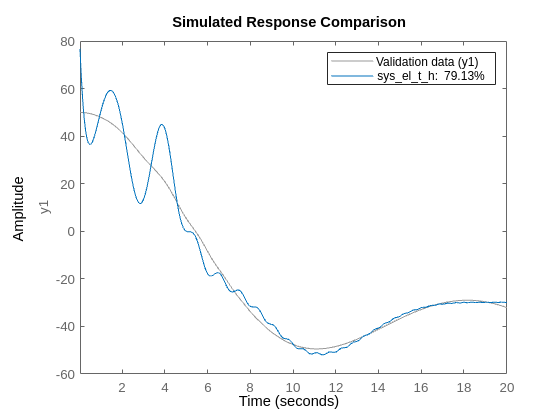

compare(data,sys_el_t_h)

## elevator to gamma

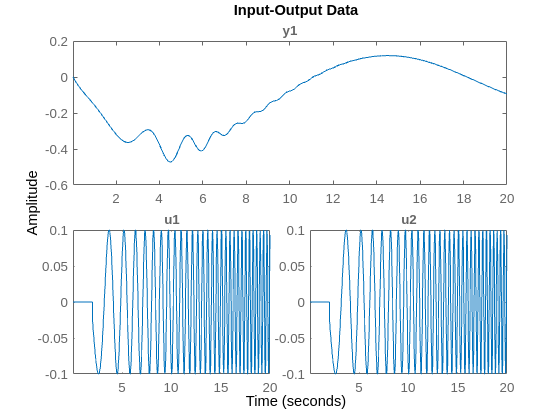

out = sim('el_t_g',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y = squeeze(out.gamma);
data = iddata(y,u,0.02);
plot(data)

sys_el_t_g= tfest(data, 3, 2)

sys_el_t_g =
  From input "u1" to output "y1":
  -2561 s^2 - 3.036e04 s - 6.309e04
  ---------------------------------
  s^3 + 420.1 s^2 + 128.4 s + 56.41
 
  From input "u2" to output "y1":
  -5274 s^2 - 6.361e04 s - 1.325e05
  ---------------------------------
  s^3 + 854.1 s^2 + 260.2 s + 114.8
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [3 3]   Number of zeros: [2 2]
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: -1599%                   
FPE: 9.725, MSE: 9.381                           
 


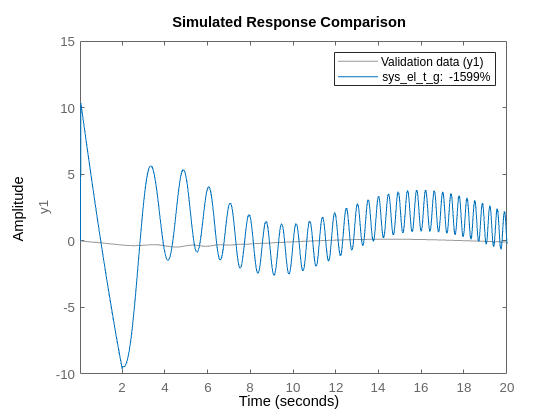

compare(data,sys_el_t_g)

# Full states - Phugoid mode(20secs)

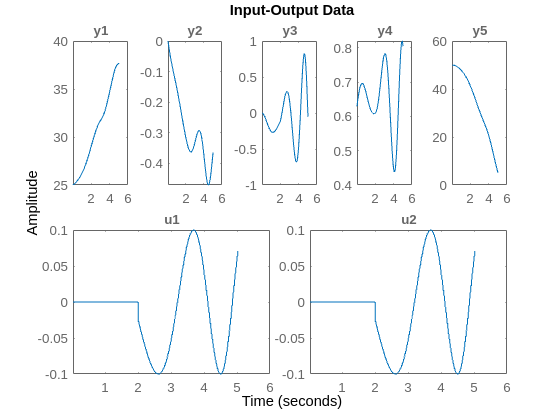

paramStruct.StopTime = "5";
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y1 = squeeze(out.velocity);
y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa);
y5 = squeeze(out.height);
y = [y1 y2 y3 y4 y5];
data = iddata(y,u,0.02);
plot(data)

sys= tfest(data, 4, 2)

sys =
  From input "u1" to output...
                 42.16 s^2 - 47.98 s + 917.3
   y1:  ----------------------------------------------
        s^4 + 0.4284 s^3 + 14.55 s^2 + 5.453 s + 1.108
 
                 -9.242 s^2 + 10.71 s - 53.65
   y2:  ----------------------------------------------
        s^4 + 3.761 s^3 + 7.937 s^2 + 7.074 s + 0.5732
 
                -3.197 s^2 - 18.09 s - 134.6
   y3:  ---------------------------------------------
        s^4 + 5.894 s^3 + 25.56 s^2 + 62.75 s + 33.61
 
                  5.618 s^2 - 7.552 s + 87.08
   y4:  -----------------------------------------------
        s^4 + 0.5094 s^3 + 14.82 s^2 + 6.762 s + 0.7239
 
                  33.18 s^2 - 111.5 s + 391.8
   y5:  -----------------------------------------------
        s^4 + 0.628 s^3 + 1.417 s^2 + 0.5214 s + 0.0383
 
  From input "u2" to output...
                   34.3 s^2 + 60.04 s + 395
   y1:  ----------------------------------------------
        s^4 + 0.4415 s^3 + 14.54 s^2 + 5.70

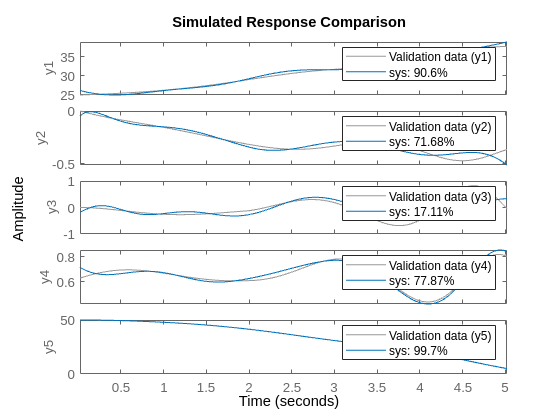

compare(data,sys)

# Full states - Phugoid mode(20secs)

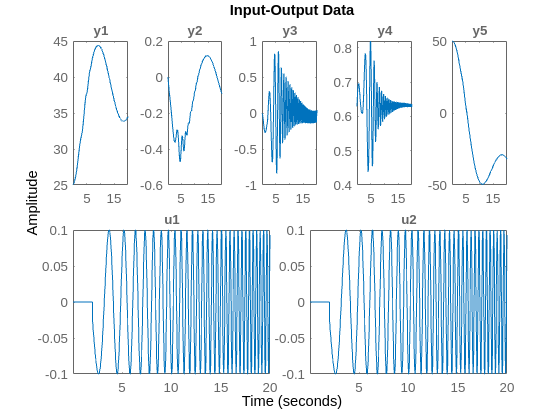

paramStruct.StopTime = "20";
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y1 = squeeze(out.velocity);
y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa);
y5 = squeeze(out.height);
y = [y1 y2 y3 y4 y5];
data = iddata(y,u,0.02);
plot(data)

sys= tfest(data, 4, 2)

sys =
  From input "u1" to output...
                  7810 s^2 + 6848 s + 9879
   y1:  ---------------------------------------------
        s^4 + 20.7 s^3 + 6.436 s^2 + 2.623 s + 0.3106
 
                -49.46 s^2 + 24.11 s - 75.97
   y2:  --------------------------------------------
        s^4 + 3.288 s^3 + 39.5 s^2 + 3.004 s + 2.125
 
             -2386 s^2 + 3.106e04 s - 5.436e04
   y3:  -------------------------------------------
        s^4 + 95.75 s^3 + 615.9 s^2 + 1955 s + 3178
 
                  -18.56 s^2 - 47.1 s + 18.97
   y4:  -----------------------------------------------
        s^4 + 3.31 s^3 + 4.231 s^2 + 1.233 s + 0.001472
 
                 1.543e04 s^2 + 6879 s - 4207
   y5:  -----------------------------------------------
        s^4 + 9.126 s^3 + 2.677 s^2 + 3.143 s + 0.08526
 
  From input "u2" to output...
             2.992e04 s^2 + 3.395e04 s + 1.543e04
   y1:  ----------------------------------------------
        s^4 + 49.13 s^3 + 6.181 s^2 + 4.988 s + 

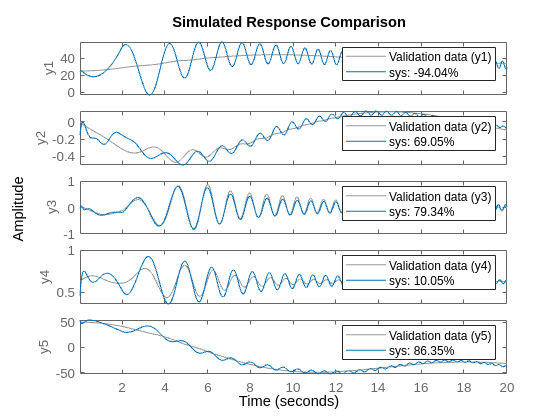

compare(data,sys)